# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `layers`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 19-Jan-2024 23:31:09

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("params_values.mat");

## Create Array of Layers

layers = [
    imageInputLayer([2 2 257],"Name","imageinput")
    transposedConv2dLayer([4 4],256,"Name","transposed-conv-1","Cropping",[1 1 1 1],"Stride",[2 2])
    transposedConv2dLayer([4 4],128,"Name","transposed-conv-2","Cropping",[1 1 1 1],"Stride",[2 2])
    transposedConv2dLayer([4 4],64,"Name","transposed-conv-3","Cropping",[1 1 1 1],"Stride",[2 2])
    transposedConv2dLayer([4 4],32,"Name","transposed-conv-4","Cropping",[1 1 1 1],"Stride",[2 2])
    transposedConv2dLayer([4 4],1,"Name","transposed-conv-5","Cropping",[1 1 1 1],"Stride",[2 2])];

## Plot Layers

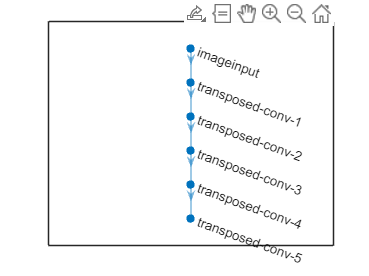

plot(layerGraph(layers));